cd('C:\Users\user\Documents\MATLAB\vLSH-master')

%CIFAR100
% rootFolder = 'cifar-100-matlab\CIFAR-100\TEST';
% categories = {'cup','dinosaur','forest','hamster'};

%COREL80
rootFolder = 'CorelDB';
categories = {'art_antiques','obj_car','sc_sunset','wl_buttrfly','bld_sculpt'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imagesPerClass = 100;
[trainingSet, ~] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
    I = imresize(I, [256 256]); % can try without this
    sift = detectSIFTFeatures(I).selectStrongest(25);
    [features, sift_points] = extractFeatures(I, sift);
    featureSet = [featureSet features.'];
    ref = [ref repmat([i], 1, size(features,1))];
end

cd('C:\Users\user\Documents\MATLAB\greg')
H = 10; %number of hash tables
key = 25; %50-bit key
lshStructgreg = lsh('lsh',H,key,size(featureSet,1),featureSet,'range',255);

 B UNLIMITED 25 keys 10 tables
898 distinct buckets
Table 1 adding 898 buckets (now 898)
Table 1: 16861 elements
900 distinct buckets
Table 2 adding 900 buckets (now 900)
Table 2: 16861 elements
302 distinct buckets
Table 3 adding 302 buckets (now 302)
Table 3: 16861 elements
506 distinct buckets
Table 4 adding 506 buckets (now 506)
Table 4: 16861 elements
421 distinct buckets
Table 5 adding 421 buckets (now 421)
Table 5: 16861 elements
1297 distinct buckets
Table 6 adding 1297 buckets (now 1297)
Table 6: 16861 elements
424 distinct buckets
Table 7 adding 424 buckets (now 424)
Table 7: 16861 elements
860 distinct buckets
Table 8 adding 860 buckets (now 860)
Table 8: 16861 elements
246 distinct buckets
Table 9 adding 246 buckets (now 246)
Table 9: 16861 elements
419 distinct buckets
Table 10 adding 419 buckets (now 419)
Table 10: 16861 elements


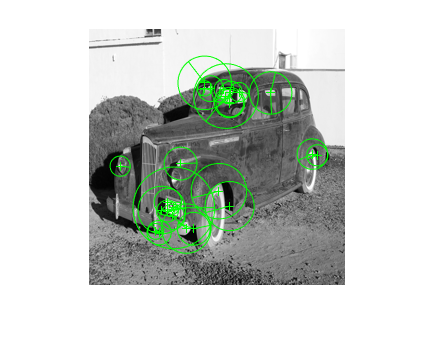

cd('C:\Users\user\Documents\GitHub\Content-based-Image-Retrieval')
% query an input image
I = imread("car1.jpg");
I = imresize(im2gray(I), [256 256]);
figure, imshow(I); hold on;
sift = detectSIFTFeatures(I).selectStrongest(25);
[queryFeatures, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);

queryFeatures = queryFeatures.';
idsMULTIPROBE = zeros(size(queryFeatures, 1), 32);
cd('C:\Users\user\Documents\MATLAB\greg')
for i = 1:size(queryFeatures, 1)
    [nnlsh,numcand]=lshlookup(queryFeatures(:,1),featureSet,lshStructgreg,'k',K,'distfun','lpnorm','distargs',{1});
    idsMULTIPROBE(i,:) = nnlsh;
end
idsMULTIPROBE = idsMULTIPROBE.';

% convert the feature IDs into their original image IDs
oriImages = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          oriImages(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

% aggregate and weight the image features by their ranks 
uniqImageIds = unique(oriImages);
N = numel(uniqImageIds);
weights = zeros(N,1);
fib = zeros(1, K); fib(K-1) = 1;
for i = K-2:-1:1
   fib(i) = fib(i+1)+fib(i+2);
end

for k = 1 : N
    weights(k) = sum(sum(oriImages == uniqImageIds(k))); % unranked weighting of NNs
    % ranked weighting of NNs
%   weights(k) = sum((K + (0 : K - 1) * -1) * (oriImages == uniqImageIds(k)));  % linear
%   weights(k) = sum(flip(exp(1 : K)) * (oriImages == uniqImageIds(k))); % exponential
%   weights(k) = sum(fib * (oriImages == uniqImageIds(k))); % fibonacci
end

ranks = sortrows([weights uniqImageIds], 1, 'descend');


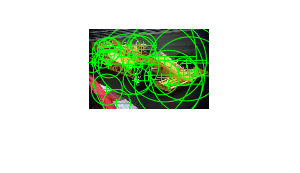

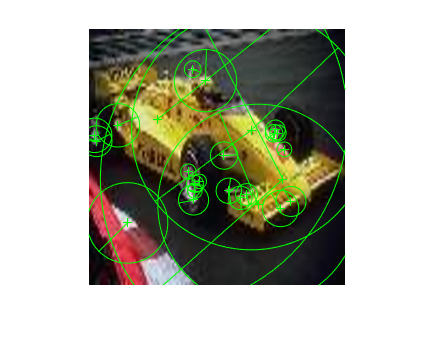

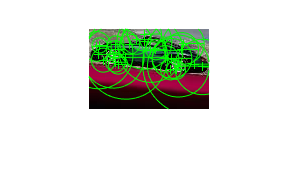

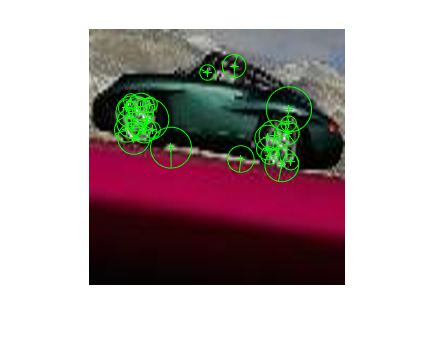

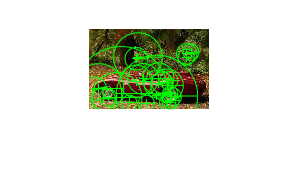

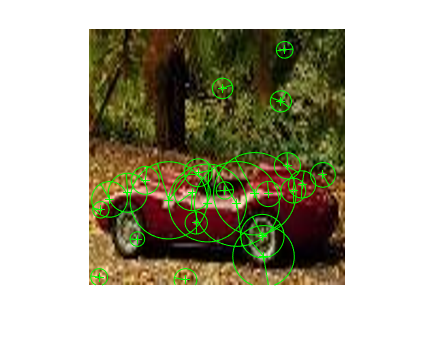

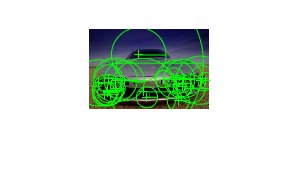

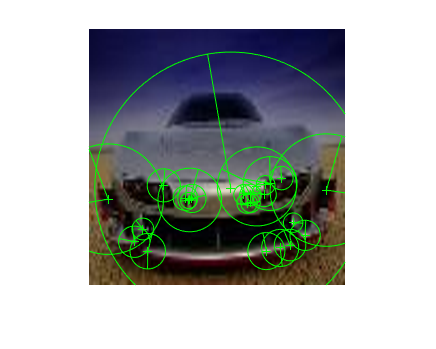

% display top 20 the matching images
for pic = 1 : min(20, length(ranks))
    if ranks(pic,2)>0
        % plot original image
        I = readimage(trainingSet, ranks(pic, 2));
        figure, imshow(I); hold on;
        sift = detectSIFTFeatures(im2gray(I)).selectStrongest(25);
        plot(sift,'showOrientation',true);

        % plot resized image
        I = imresize(I, [256 256]);
        figure, imshow(I); hold on
        I = im2gray(I);
        sift = detectSIFTFeatures(I).selectStrongest(25);
        [queryFeatures, valid_points] = extractFeatures(I, sift);
        plot(valid_points,'showOrientation',true);
    end
end